% Create individual element
freq = 900e6;
vp = physconst('lightspeed');
lambda = vp/freq;
d = dipole;
d.Length = 0.157;
d.Width = 0.002;

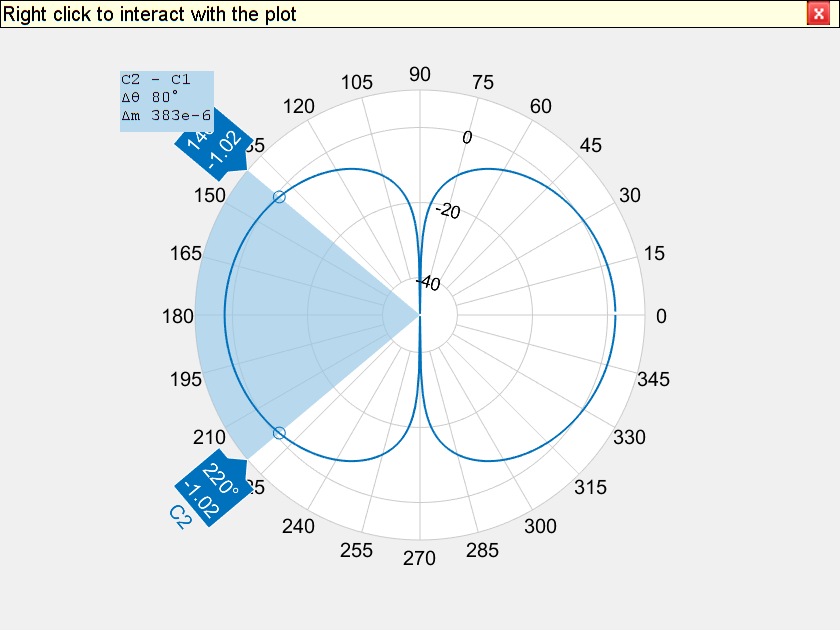

% Plot and calculate beamwidth
beamwidth(d,freq,0,1:1:360);

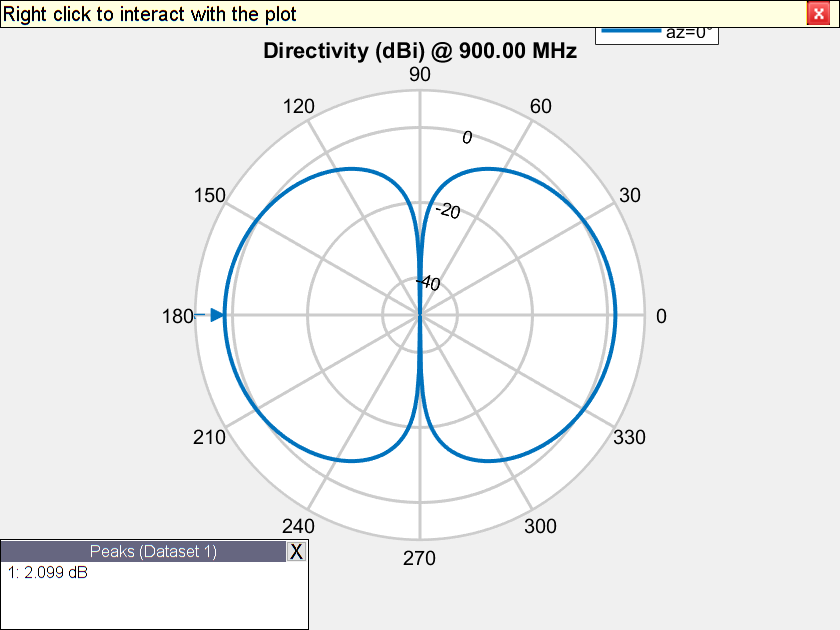

% Polar radiation pattern plot
h(2) = figure;
patternElevation(d,freq);

% Show radiation pattern
pattern3Dfig = figure;
pattern(d,freq);
patternazfig1 = figure;
az_angle = 1:0.25:180;
pattern(d,freq,0,az_angle,'CoordinateSystem','rectangular')
axis([0 180 -25 15]);